## Mie散射

本段code复现Absorption and scattering of light by small particles这本书第四章的Mien散射内容

## 角度依赖的tao函数和pi函数

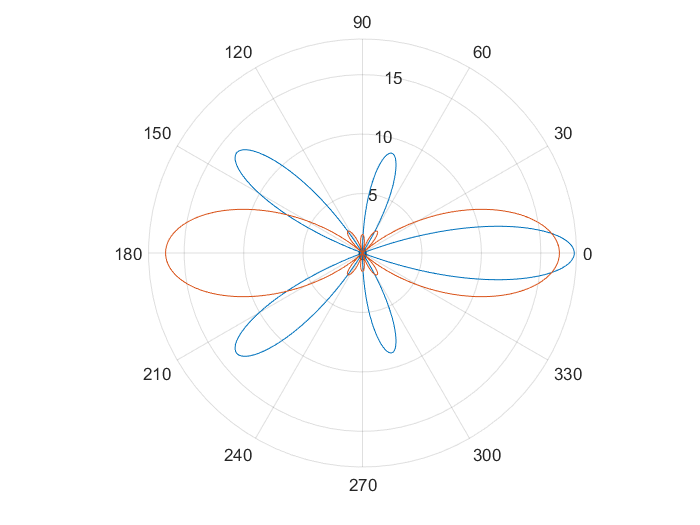

clear
theta = linspace(0,2*pi,1000);
% Tao = zeros(size(theta));
% Pi = zeros(size(theta));
% for ii = 1:length(theta)
%     [Tao(ii),Pi(ii)] = TP(3,theta(ii));
% end
[Tao,Pi] = TP(5,theta);
figure
polarplot(theta,Tao)
hold on
polarplot(theta,Pi)

% rlim([-10 10])
% hold on
% polarplot(theta,3*cos(theta))

## 矢量图

clear 
close all
n = 3;
theta = pi/2;
rho = linspace(0,2*pi,100);
phi = linspace(0.0001,2*pi,100);
[phi,rho] = meshgrid(phi,rho);
[Tao,Pi] = TP(n,theta);

An = cos(phi)*n*(n+1).*sin(theta).*besselh(n,rho)./rho.*Pi;
Bn = cos(phi).*Tao.*r_bessel(n,rho)./rho;
Cn = -sin(phi).*Pi.*r_bessel(n,rho)./rho;
un = An.*sin(theta).*cos(phi) + Bn.*cos(theta).*cos(phi) - sin(phi).*Cn;
vn = An.*sin(theta).*sin(phi) + Bn.*cos(theta).*sin(phi) + cos(phi).*Cn;

% Am = cos(phi).*Pi;
% Bm = -sin(phi).*Tao;
% um = Am.*cos(theta).*cos(phi) - Bm.*sin(phi);
% vm = -Am.*sin(theta);
[x,y,~] = sph2cart(phi,pi/2-theta,rho);
figure
quiver(x,y,un,vn)

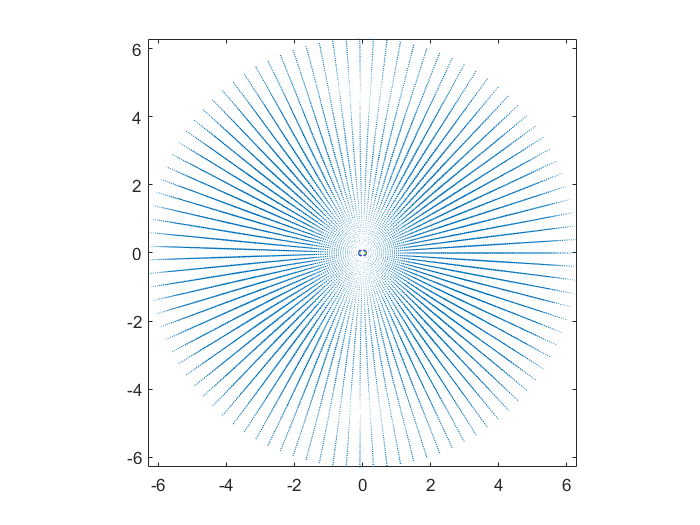

axis equal
hold on
contour(x,y,abs(An.^2 + Bn.^2 + Cn.^2))

% 
% figure
% quiver(x,z,um,vm)
% axis equal

## Mie散射

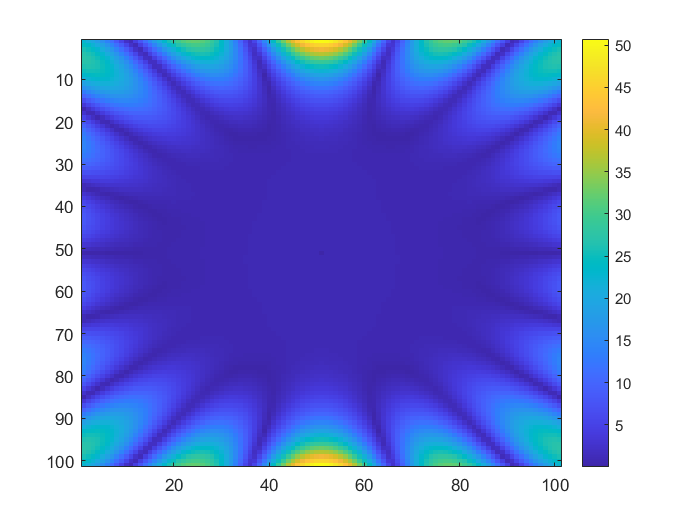

clear
close all
lambda = 670*1e-9;  % 波长
N = 1.33;   % 环境折射率
N1 = 1.51;  % 颗粒折射率
a = 0.1*lambda;   % 颗粒半径
m = N1/N;
x = 2*pi/lambda*N*a;
k = 2*pi/lambda*N;  % 环境中波矢

% 定义观察平面
X = linspace(-1*lambda,1*lambda,101);
Z = X;
[X,Z] = meshgrid(X,Z);
rho = sqrt(X.^2+Z.^2);
theta = acos(Z./rho);
phi = zeros(size(theta));
phi(X>0) = 0;
phi(X<0) = pi;

Ei_sph = zeros([size(X),3]);  % 球坐标系下入射场
Es_sph = Ei_sph;    % 球坐标系下散射场
Ep_sph = Ei_sph;    % 球坐标系下颗粒内部电场

n = 20;  % 累加次数
for ii = 1:n
    En = (1i)^ii*(2*ii+1)/ii/(ii+1);
    [an,bn,cn,dn] = Mie_coef(x,m,ii);
    [Tao,Pi] = TP(ii,theta);
    [Mi,Ni] = Vec_Wave_Fun(1,ii,theta,phi,k*rho);
    [Mp,Np] = Vec_Wave_Fun(1,ii,theta,phi,m*k*rho);
    [Ms,Ns] = Vec_Wave_Fun(3,ii,theta,phi,k*rho);
    Mi = Trans_Sph_2_Cart(Mi,theta,phi);
    Ni = Trans_Sph_2_Cart(Ni,theta,phi);
    Mp = Trans_Sph_2_Cart(Mp,theta,phi);
    Np = Trans_Sph_2_Cart(Np,theta,phi);
    Ms = Trans_Sph_2_Cart(Ms,theta,phi);
    Ns = Trans_Sph_2_Cart(Ns,theta,phi);
    Ei_sph = Ei_sph + (Mi - 1i*Ni)*En;
    Ep_sph = Ep_sph + (cn*Mi - 1i*dn*Ni)*En;
    Es_sph = Es_sph + (1i*an*Ns - bn*Ms)*En;
end
% Ei_cart = Trans_Sph_2_Cart(Ei_sph,theta,phi);
% Es_cart = Trans_Sph_2_Cart(Es_sph,theta,phi);
for ii = 1:3
    temp = squeeze(Es_sph(:,:,ii));
    temp(rho<=a) = 0;
    Es_sph(:,:,ii) = temp;
end
    
figure
imagesc((abs(Es_sph(:,:,3))))
colorbar

function [tao_n,pi_n] = TP(n,theta)

    tao_n = zeros(size(theta));
    pi_n = zeros(size(theta));
    
    temp_pi = zeros([n+1 size(theta)]); % 为了装pi0，所以要生成n+1长度的向量
    temp_pi(1,:,:) = 0;
    temp_pi(2,:,:) = 1;
    if n == 1
        pi_n = 1;
        tao_n = cos(theta);
    elseif n > 1
        for ii = 3:(n+1)
            m = ii - 1; 
            % ii对应书上第n个值，但是由于temp_pi中多装了一个pi0，
            % 所以ii比实际的n大1，这里用m代替序列号ii
            temp_pi(ii,:,:) = reshape((2*m-1)/(m-1)*cos(theta).*reshape(temp_pi(ii-1,:,:),size(theta)) ...
                - n/(n-1)*reshape(temp_pi(ii-2,:,:),size(theta)),[1,size(theta)]);
        end
        pi_n = reshape(temp_pi(end,:,:),size(pi_n));
        tao_n = n*cos(theta).*pi_n - (n+1)*reshape(temp_pi(end-1,:,:),size(pi_n));
    end
end

function [an,bn,cn,dn] = Mie_coef(x,m,n)
    syms rho 
    f1 = rho*sqrt(pi/2/rho)*besselj(n+0.5,rho);
    f2 = diff(f1,'rho');
    f3 = rho*sqrt(pi/2/rho)*besselh(n+0.5,rho);
    f4 = diff(f3,'rho');
    RB_psi = matlabFunction(f1);
    dRB_psi = matlabFunction(f2);
    RB_ksi = matlabFunction(f3);
    dRB_ksi = matlabFunction(f4);
    
    an = (m*RB_psi(m*x)*dRB_psi(x) - RB_psi(x)*dRB_psi(m*x))/...
        (m*RB_psi(m*x)*dRB_ksi(x) - RB_ksi(x)*dRB_psi(m*x));
    
    bn = (RB_psi(m*x)*dRB_psi(x) - m*RB_psi(x)*dRB_psi(m*x))/...
        (RB_psi(m*x)*dRB_ksi(x) - m*RB_ksi(x)*dRB_psi(m*x));
    
    cn = (m*RB_psi(x)*dRB_ksi(x) - m*RB_ksi(x)*dRB_psi(x))/...
        (RB_psi(m*x)*dRB_ksi(x) - m*RB_ksi(x)*dRB_psi(m*x));
    
    dn = (m*RB_psi(x)*dRB_ksi(x) - m*RB_ksi(x)*dRB_psi(x))/...
        (m*RB_psi(m*x)*dRB_ksi(x) - RB_ksi(x)*dRB_psi(m*x));
end

function [M,N] = Vec_Wave_Fun(nu,n,theta,phi,rho)
    syms r mu
    f0 = matlabFunction(sqrt(pi/2./r).*besselj(mu+0.5,r)./r);
    f1 = matlabFunction(diff(r.*sqrt(pi/2./r).*besselj(mu+0.5,r),r));
    f2 = matlabFunction(sqrt(pi/2./r).*besselh(mu+0.5,r)./r);
    f3 = matlabFunction(diff(r.*sqrt(pi/2./r).*besselh(mu+0.5,r),r));
    
    M = zeros([size(theta),3]);
    N = M;
    [Tao,Pi] = TP(n,theta);
    if nu == 1
        M(:,:,2) = cos(phi).*Pi.*rho.*f0(n,rho);
        M(:,:,3) = -sin(phi).*Tao.*rho.*f0(n,rho);
        N(:,:,1) = cos(phi)*n*(n+1).*sin(theta).*Pi.*f0(n,rho);
        N(:,:,2) = cos(phi).*Tao.*f1(n,rho)./rho;
        N(:,:,3) = -sin(phi).*Pi.*f1(n,rho)./rho;
    elseif nu == 3
        M(:,:,2) = cos(phi).*Pi.*rho.*f2(n,rho);
        M(:,:,3) = -sin(phi).*Tao.*rho.*f2(n,rho);
        N(:,:,1) = cos(phi)*n*(n+1).*sin(theta).*Pi.*f2(n,rho);
        N(:,:,2) = cos(phi).*Tao.*f3(n,rho)./rho;
        N(:,:,3) = -sin(phi).*Pi.*f3(n,rho)./rho;
    end
end

function E_cart = Trans_Sph_2_Cart(Ei_sph,theta,phi)

    E_cart(:,:,1) = sin(theta).*cos(phi).*squeeze(Ei_sph(:,:,1)) ...
        + cos(theta).*cos(phi).*squeeze(Ei_sph(:,:,2)) ...
        - sin(phi).*squeeze(Ei_sph(:,:,3));
    E_cart(:,:,2) = sin(theta).*sin(phi).*squeeze(Ei_sph(:,:,1)) ...
        + cos(theta).*sin(phi).*squeeze(Ei_sph(:,:,2)) ...
        + cos(phi).*squeeze(Ei_sph(:,:,3));
    E_cart(:,:,3) = cos(theta).*squeeze(Ei_sph(:,:,1)) ... 
        - sin(theta).*squeeze(Ei_sph(:,:,2));

end